
fpms = [100 581]; %-- frames per millisecond
micronsPerPixel = [12.5 160]; %-- in x axis
z2xRatio = 3.7;

minAmplitudes = [-0.9852 -0.98];
maxAmplitudes = [-0.9847 -0.973];
smoothing = [27 81 3; 1 5 7];

trimmed1 = experiment1(14:end-14,50:end, 1:end);
trimmed2 = experiment2(1:end,1:end, 1:end);

smoothed1 = smooth3(-trimmed1, 'box', smoothing(1,:));
smoothed2 = smooth3(-trimmed2, 'box', smoothing(2,:));

scaled1 = ScaleImage(smoothed1,z2xRatio);
scaled2 = ScaleImage(smoothed2,z2xRatio);

normalized1 = NormalizeMat(scaled1,minAmplitudes(1), maxAmplitudes(1));
normalized2 = NormalizeMat(scaled2,minAmplitudes(2), maxAmplitudes(2));

totalTime = size(normalized2, 3)/fpms(2);
msPerFrame = 1/fpms(2);

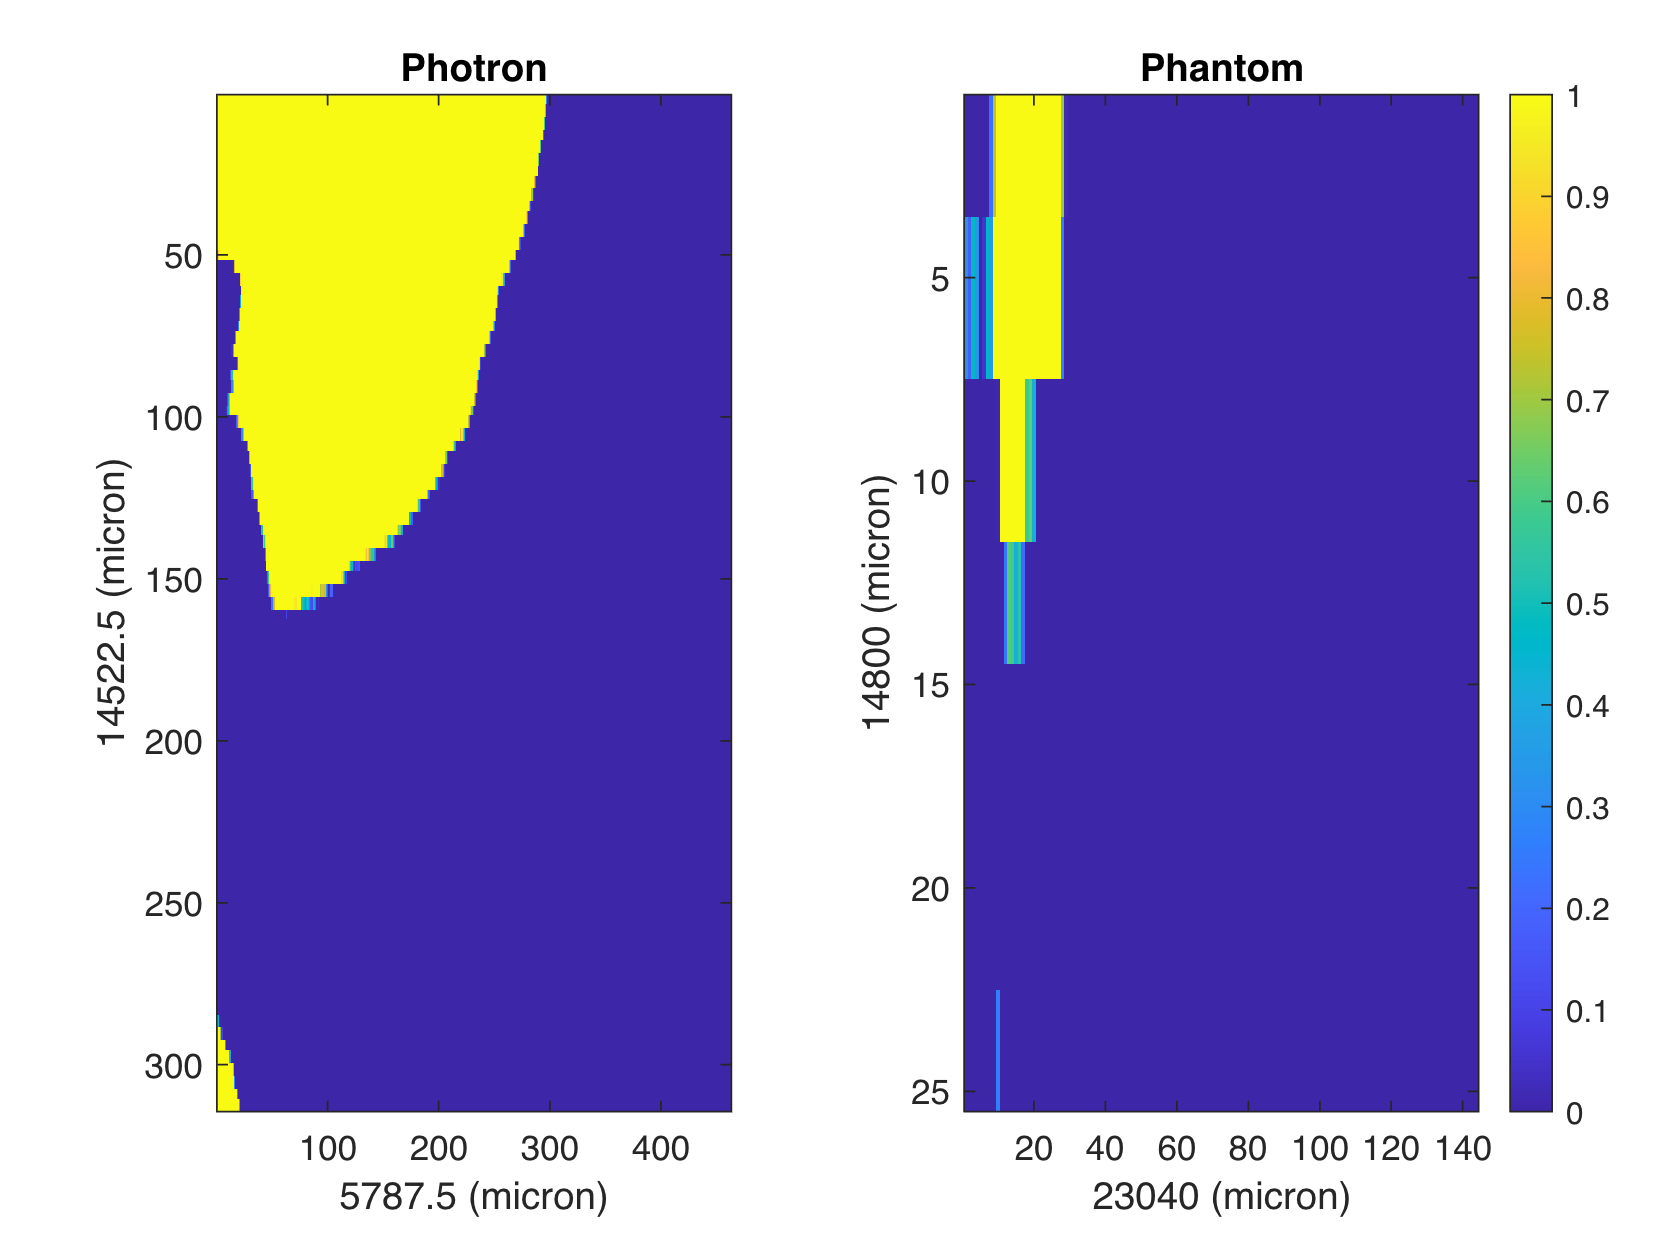


t =0.9242685025817556;

current1 = normalized1(:,:,round(t*fpms(1))+1);
current2 = normalized2(:,:,round(t*fpms(2))+1);

tiledlayout(1,2);

nexttile;
imagesc(current1);
caxis([0 1]);

title("Photron");
xlabel(micronsPerPixel(1) * size(current1,2) + " (micron)");
ylabel(micronsPerPixel(1) * z2xRatio* size(current1,1) + " (micron)");


nexttile;
imagesc(current2);
caxis([0 1]);
colorbar;

title("Phantom");
xlabel(micronsPerPixel(2) * size(current2,2) + " (micron)");
ylabel(micronsPerPixel(2) * z2xRatio* size(current2,1) + " (micron)");

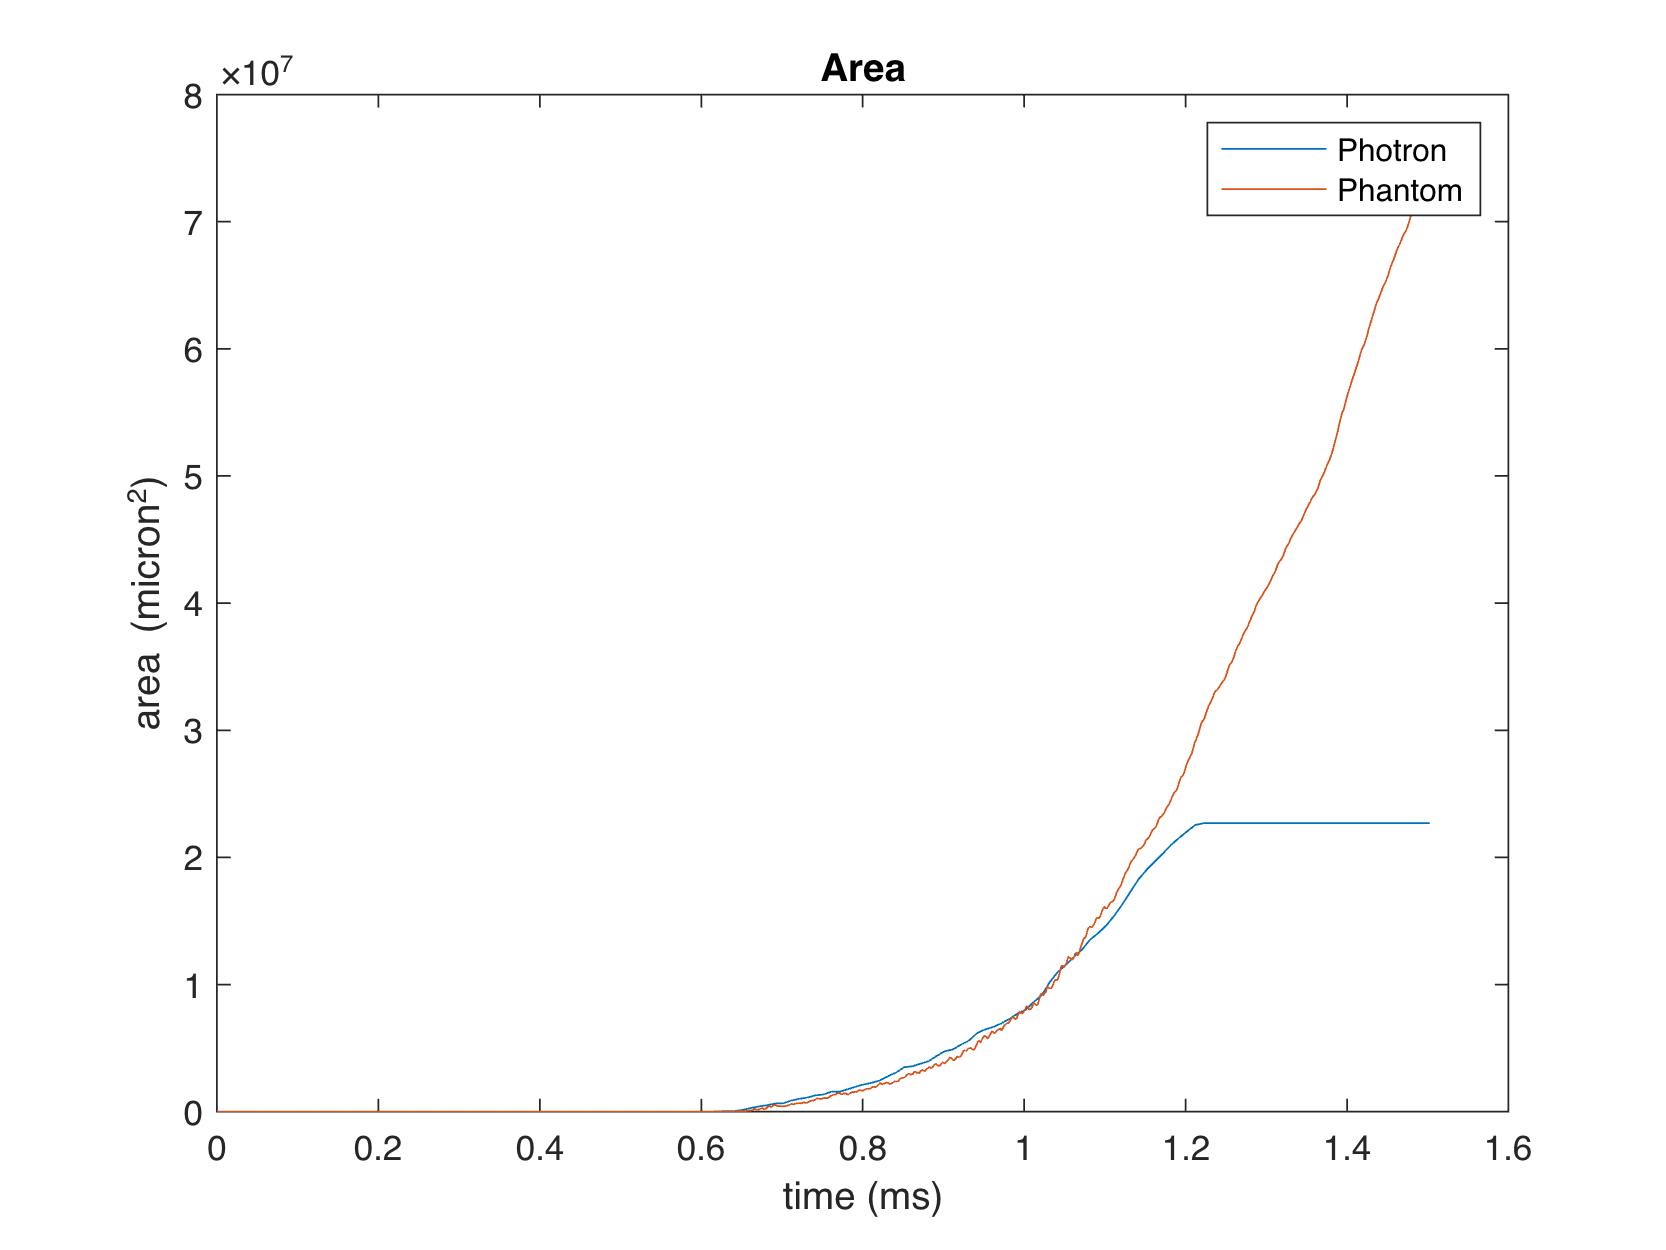

timeSize1 = size(experiment1,3);
timeLine1 = linspace(0,totalTime,timeSize1);
timeSize2 = size(experiment2,3);
timeLine2 = linspace(0,totalTime,timeSize2);

[Area1,Perimeter1,Beta1] = GetParameters(normalized1,micronsPerPixel(1));
[Area2,Perimeter2,Beta2] = GetParameters(normalized2,micronsPerPixel(2));

figure;
plot(timeLine1, Area1);
hold on;
plot(timeLine2, Area2);
title("Area");
xlabel("time (ms)");
ylabel("area (micron^2)");
legend("Photron", "Phantom");
hold off;

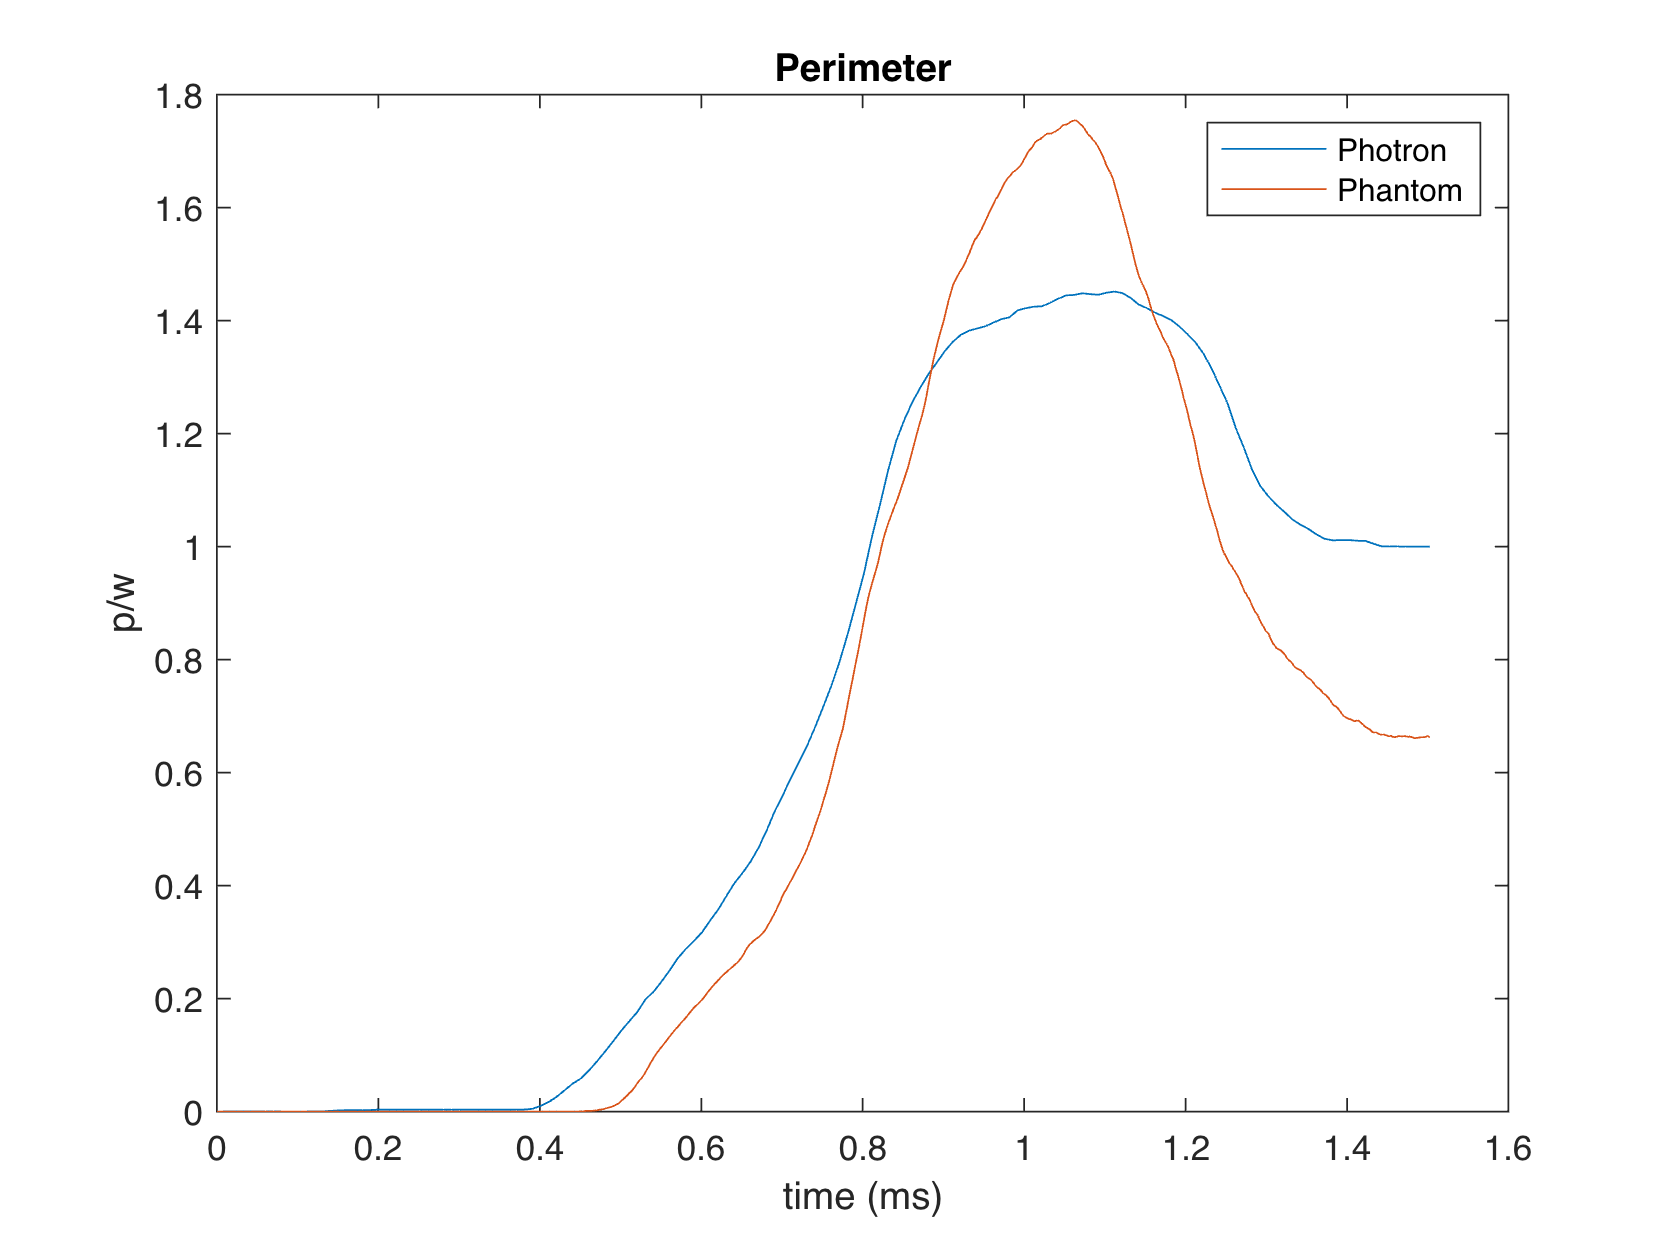


plot(timeLine1, smoothdata(Perimeter1));
hold on;
plot(timeLine2, smoothdata(Perimeter2));
title("Perimeter");
xlabel("time (ms)");
ylabel("p/w");
legend("Photron", "Phantom");
hold off;

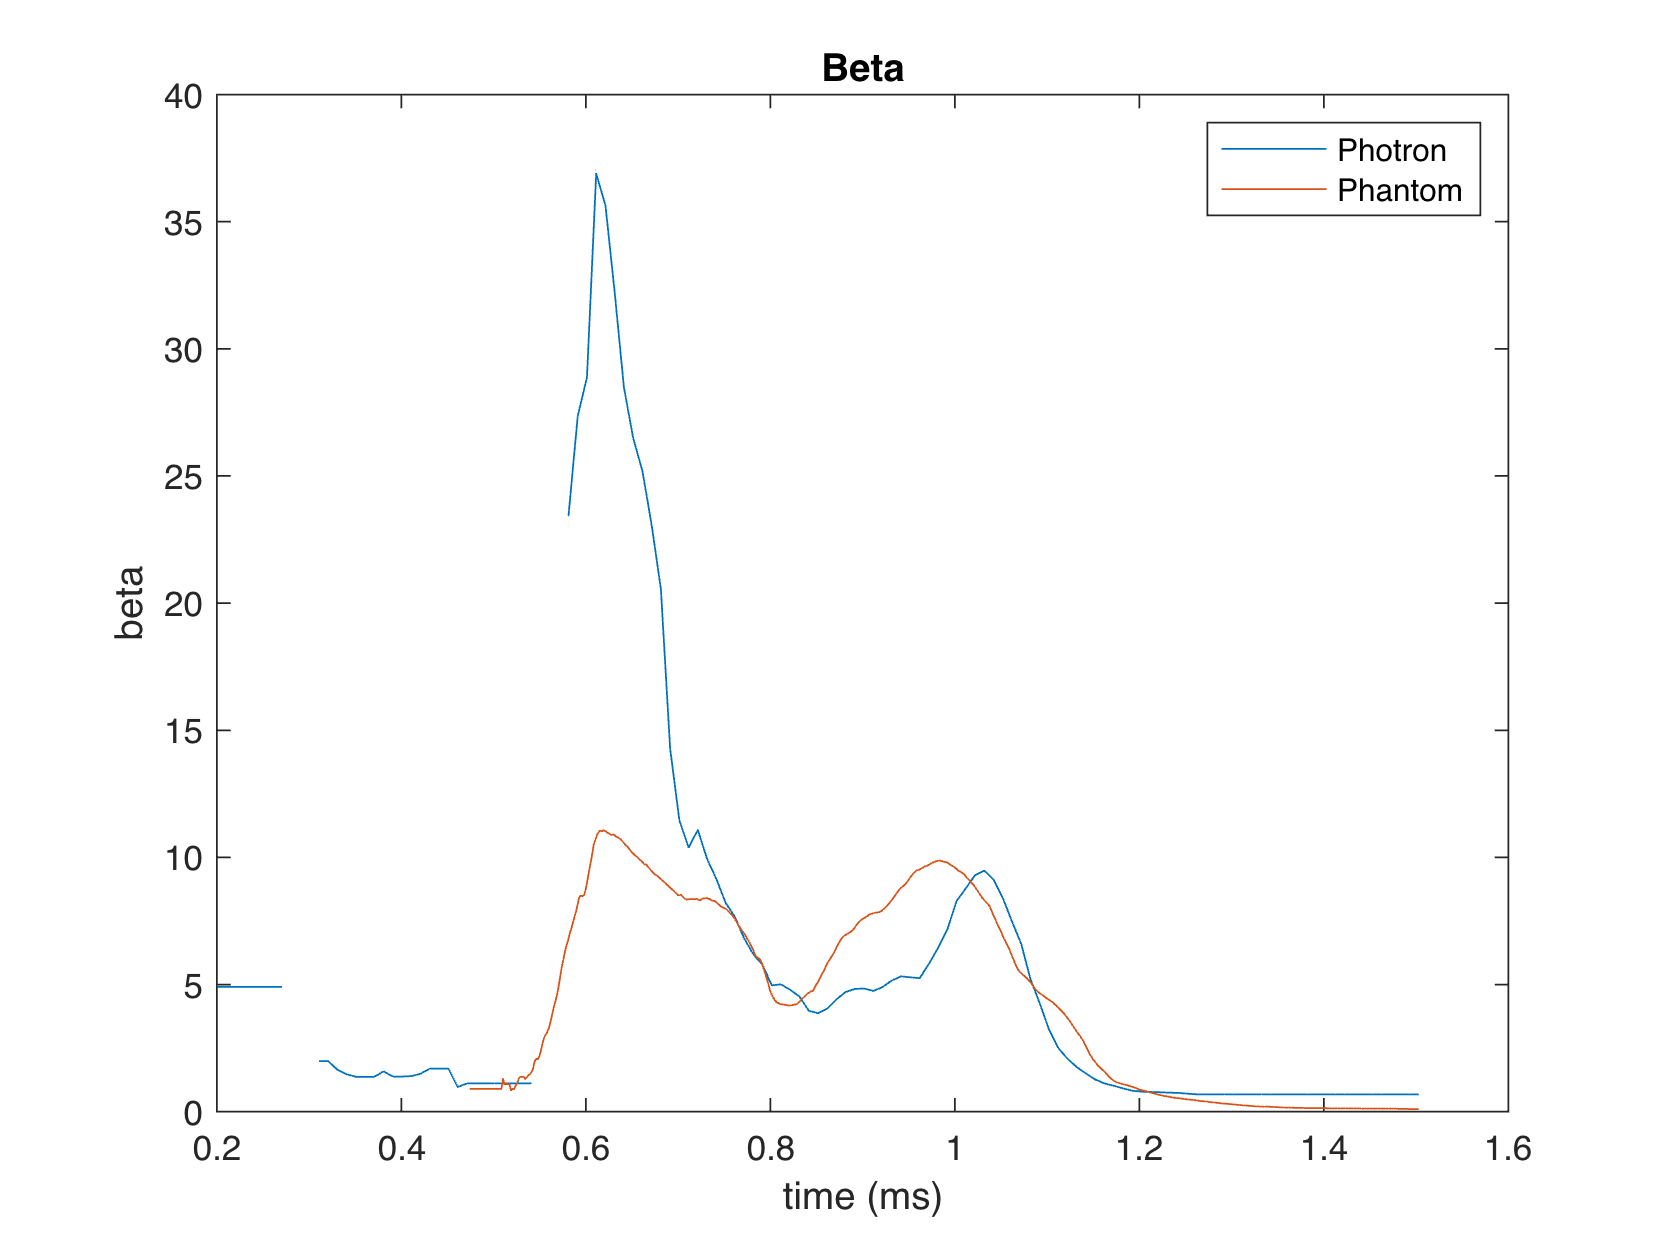


plot(timeLine1, smoothdata(Beta1));
hold on;
plot(timeLine2, smoothdata(Beta2));
title("Beta");
xlabel("time (ms)");
ylabel("beta");
legend("Photron", "Phantom");
hold off;

function Normalized=NormalizeMat(mat, minVal, maxVal)

    Normalized = zeros(size(mat));
    
    for i=1:size(mat,1)
        for j=1:size(mat,2)
            for k=1:size(mat,3)
                current = mat(i,j,k);
    
                if(current > maxVal)
                    if (j == size(mat,2))
                        result = 0.5;
                    else
                        result = 1;
                    end
                
                elseif (current < minVal)
                    result = 0;
                else
                    result = (current - minVal)/(maxVal - minVal);
                end
    
                Normalized(i,j,k) = result;
            end
        end
    end
end

function [Area, Perimeter, Beta] = GetParameters(mat, scaling)
    Area = zeros(size(mat,3),1);
    Perimeter = zeros(size(mat,3),1);

    for t=1:size(mat,3)
        currentMat = mat(:,:,t);
        Area(t) = sum(currentMat,'all') * scaling * scaling;
    
        currentPerimeter = 0;
        for i=1:size(currentMat,1)
            for j=1:size(currentMat,2)
                currentPixel = currentMat(i,j);
                currentPerimeter = currentPerimeter + 2 * (0.5 - abs(currentPixel - 0.5)) * scaling;
            end
        end
    
        Perimeter(t) = currentPerimeter;
    end

    Beta = (Perimeter .^2) ./ Area;

    Perimeter = Perimeter / (scaling * size(mat,1));
end